%f = @(x) 0.01*sin(10*x(1))+(0.07*x(1).^2-0.4).^2
f = @(x) (x - 2).^2 

f = function_handle with value:
    @(x)(x-2).^2




[a, b, i] = expansion(f, 2, 2.1, 2, 1000)

a = 2.1000

b = 1.9000

i = 0

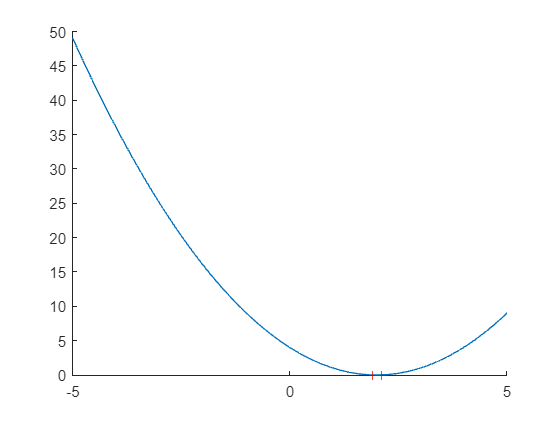

figure;
hold on;
fplot(f);
plot([a, b], [0, 0], '|r');

function [a, b, i] = expansion(f, xzero, x1, alpha, Nmax)

x0 = xzero;
i = 0;
if f(x0) == f(x1)
    a = x0;
    b = x1;
    return
end

if f(x1) > f(x0)
    x1 = -1*(x1 - xzero) + xzero;
    if f(x1) == f(-1*(x1 - xzero) + xzero)
        a = -1*(x1 - xzero) + xzero;
        b = x1;
        return
    end
end

x2 = x1;
x1 = x0;
while f(x1) > f(x2)
    if i > Nmax
        a = -inf;
        b = inf;
        return 
    end
    i = i + 1;
    x0 = x1;
    x1 = x2
    x2 = alpha * (x2 - xzero) + xzero
end

if x0 < x2
    a = x0;
    b = x2;
    return
end
a = x2;
b = x0;
return;
end